% First-order and second-order IIR filters are useful and provide simple examples, but, 
% in many cases, we use higher-order IIR filters because they can realize better 
% frequency responses with flatter passbands and stopbands and sharper transition regions.
% The butter, cheby1, cheby2, and ellip functions in MATLAB Signal Processing Toolbox 
% can be used to design filters with prescribed frequency-selective characteristics. 
% Example of an IIR low pass filter
bb=[0.0798 0.0798 0.0798 0.0798];
aa=[1 -1.556 1.272 -0.398];

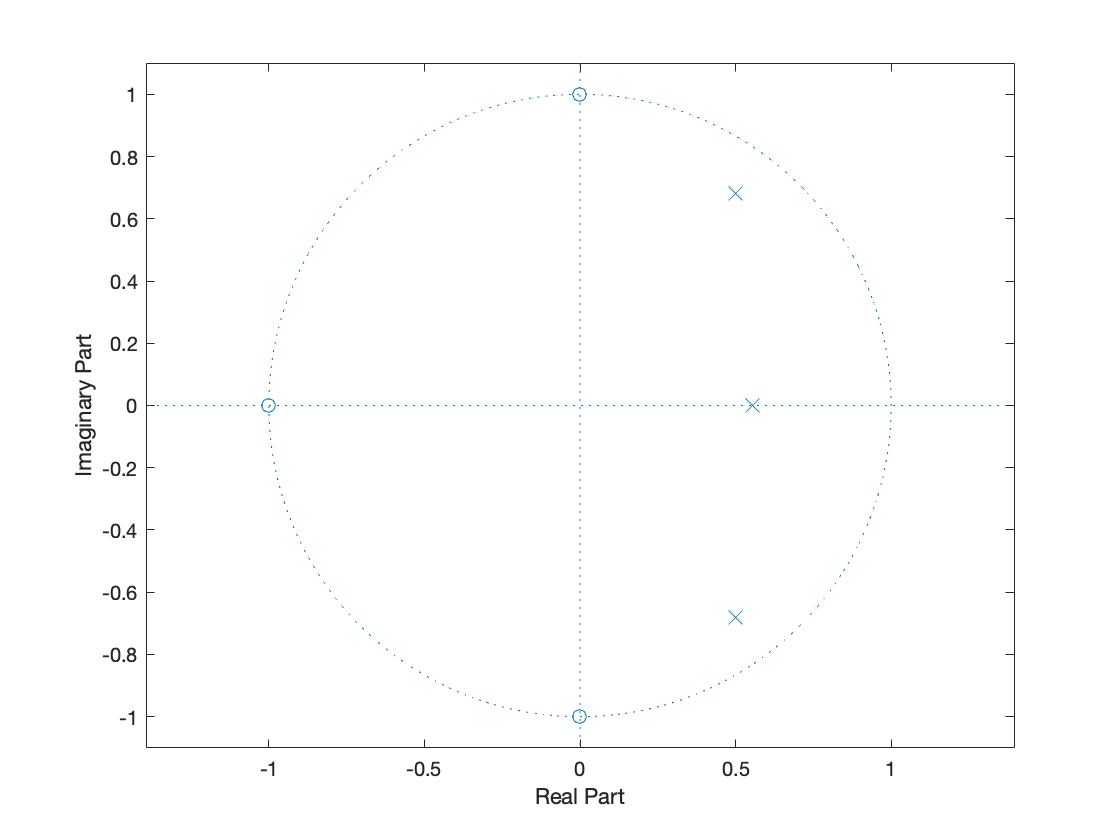

% Zero-pole plot
zplane(bb,aa)

% Note: All the zeros are on the unit circle and that all the poles are strictly inside the unit circle, as they must be for a stable system

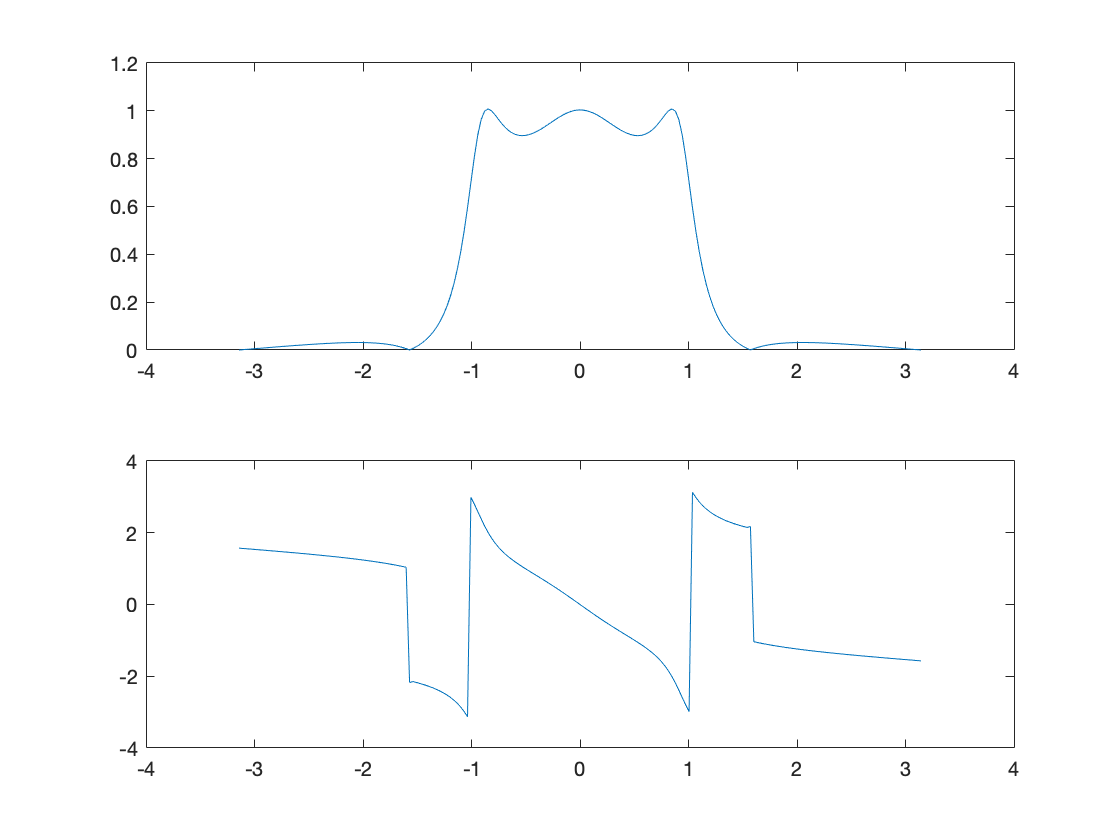

% Plot of the frequency response
t=-pi:(pi/100):pi;
HH = freqz(bb, aa,t);
subplot(2,1,1)
plot(t,abs(HH))
subplot(2,1,2)
plot(t,angle(HH))

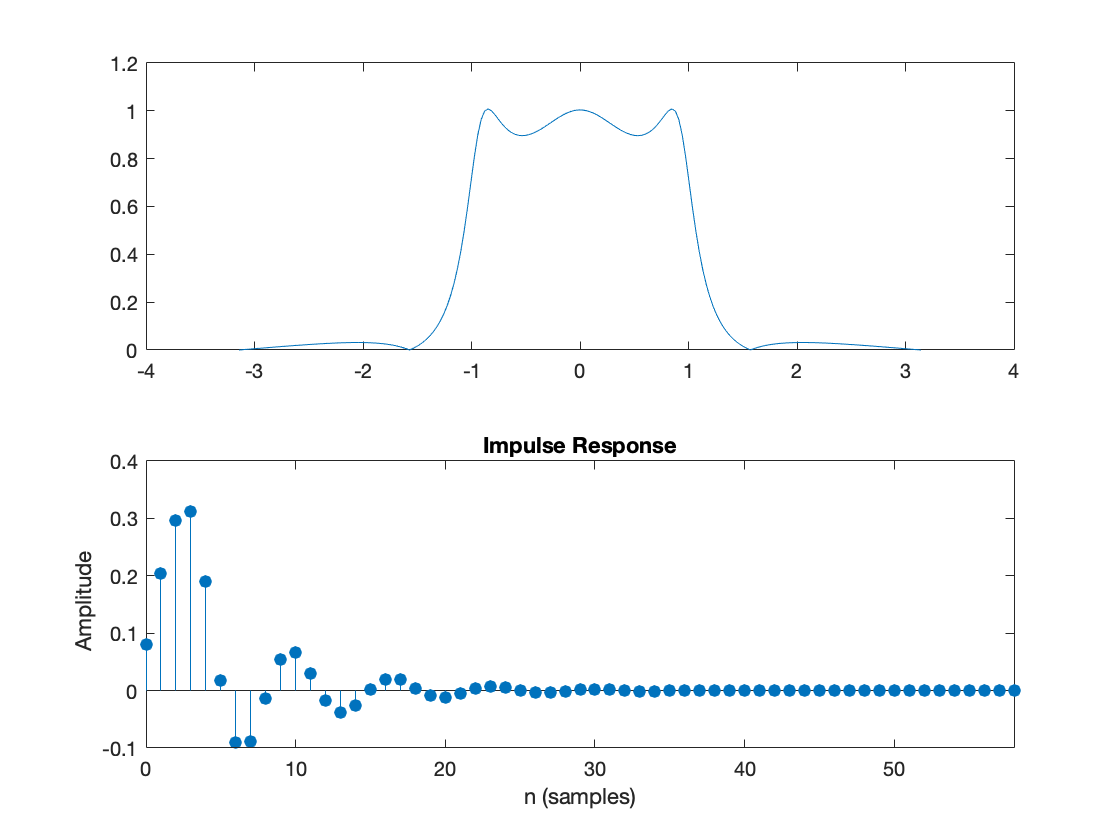

% Plot of the impulse response
impz(bb,aa)